format shortg
clear all

# Oppgave 1

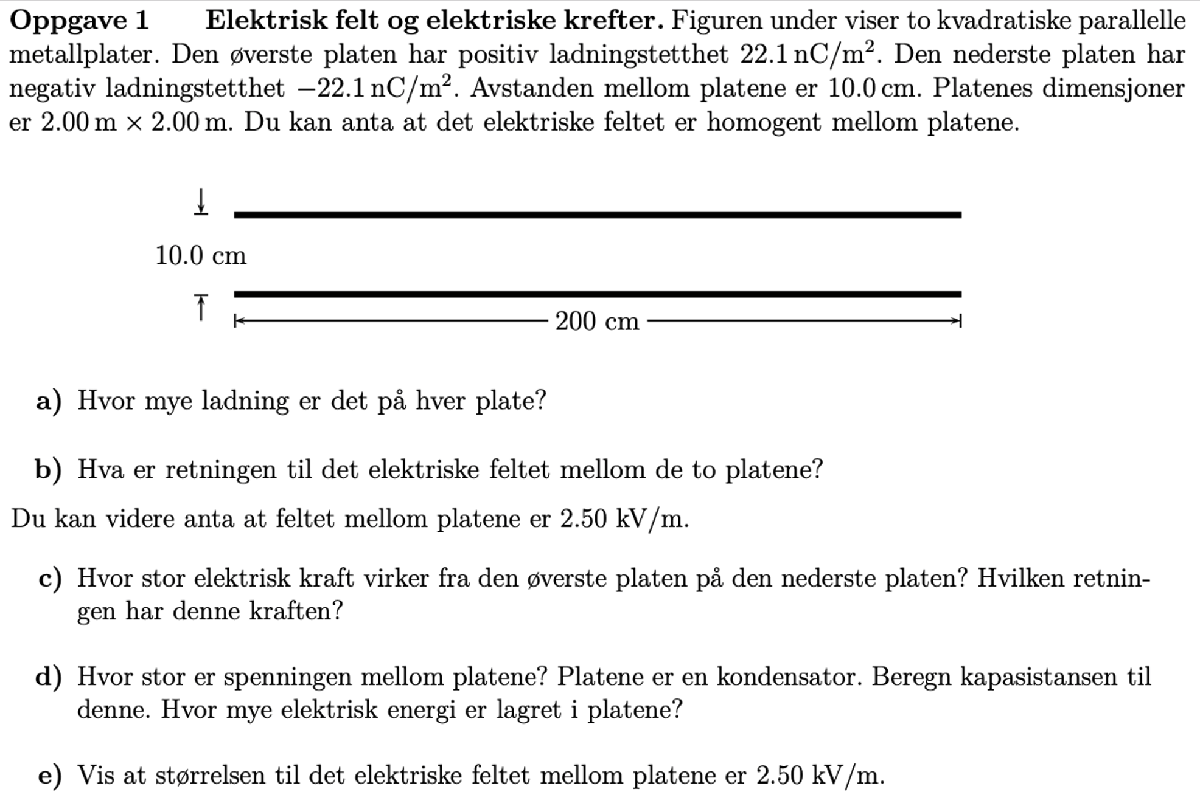

plate_p =  22.1 * 10^-9; % C/m^2
plate_n = -plate_p; % C/m^2
d = 10.0 * 10^-2; % meter
A = 2*2; % m^2

a)

Q = plate_p * A

Q =      8.84e-08


b)

Feltet går fra positivt til negativt.

c)

E = 2.50 * 10^3; %V/m

Later som platen er en punktladning i et uniformt felt:

F = Q * E

F =      0.000221


Eller hvis man er teit:

F = Q * E/2

F =     0.0001105


d)

V = E * d

V =    250



$$C=\frac{Q}{U_{\mathrm{ab}} }$$


C = Q/V

C =     3.536e-10



$$U=\frac{1}{2}\mathrm{QV}$$


U = Q*V/2

U =     1.105e-05


e)


$$E=\frac{\sigma }{\epsilon_0 }=\frac{\mathrm{ladningstetthet}}{\epsilon_0 }$$


E = plate_p/e_0

E =          2496


# Oppgave 2

p_kobber = 1.70 * 10^-8; %Ohm meter
massetetthet = 8960; % kg/m^3

Forstår det slik at den første tråden kuttes for å få 7 like lange deler, disse tvinnes så til en ny tråd som er $1/7$ så lang som den første og Arealet blir da 7ganger større. 


$$R=p\frac{l}{A}$$
  

Som betyr at siden vi får dette regnestykket etter at tråden har blitt endret:


$$R=p*\frac{1/7*l}{7*A}=p*\frac{l}{7}*\frac{1}{7A}=\frac{p*l}{49A}$$


originalt hadde vi at:


$$1\ldotp 00=p*1*\left(\frac{l}{A}\right)$$


og når har vi:


$$R=p*\frac{1}{49}*\frac{l}{A}\Rightarrow \frac{R}{49}=p*\frac{l}{A}$$


R = signif(1/49, 3);
fprintf('R = %.1f milliOhm', R*10^3)

R = 20.4 milliOhm

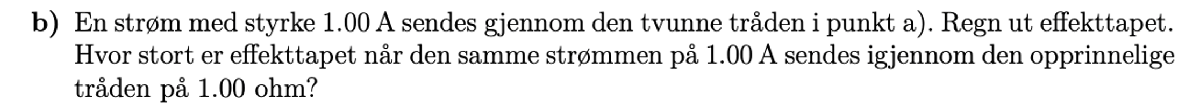


$$P={I*V}_{\textrm{ab}} =I^2 *R$$


I = 1.00; % Ampere
P = I^2*R

P =        0.0204


ElektriskEffekt(0,0,1.00,R)

ans =        0.0204


P = I^2*1.00

P =      1


ElektriskEffekt(0,0,1.00,1.00)

ans =      1


Vi ønsker altså å få en så lang som mulig kobberledning ved å bruke kun 1.00kg kobber med resistanse på 1.00 Ohm. Vi vet at jo tykkere ledningen er, jo mindre resistanse er det per meter, men lengden blir da kortere. PÅ den andre siden, hvis ledningen er svært tynn kan ledningen være lengre, men her er det resistansen som hindrer lengden, da resistansen er høyerer gjennom en tynnere ledning. Vi ønsker altså å finne det perfekte punktet slik at vekten og resistansen begrenser til samme verdi? gi høyest verdi for $l$. Først finner vi hva volumet av ledningen vil være, dette vil være likt uansett lengde på tråden ettersom vekten/massen er konstant.


$$m=V*\textrm{massetetthet}\Rightarrow V=\frac{m}{\textrm{massetetthet}}$$


V = 1.00/massetetthet

V =    0.00011161


når vi vet volumet, ønsker vi nå kun å finne ut hva den største verdien for $l$ kan være for å få dette volumet:

Samtidig vet vi at Resistansen skal være $1\ldotp 00\;\textrm{Ohm}$, vi har nå likningssettet:


$$R=p*\frac{l}{A}=1\ldotp 00$$



$$V=l*A$$
    

som gir:


$$A=p*l$$


$l*\left(p*l\right)=V\Rightarrow l^2 =\frac{V}{p}\Rightarrow l=\pm \sqrt{\frac{V}{p}}$ og siden lengden kun kan være positiv får vi:


$$l=\sqrt{\frac{V}{p}}$$


l = signif(sqrt(V/p_kobber), 3) % meter

l =     81


# Oppgave 4

c) Dette er en en "ELLER" krets ettersom at det kun trengs å lukkes én bryter for at dioden skal lyse.

# Oppgave 5

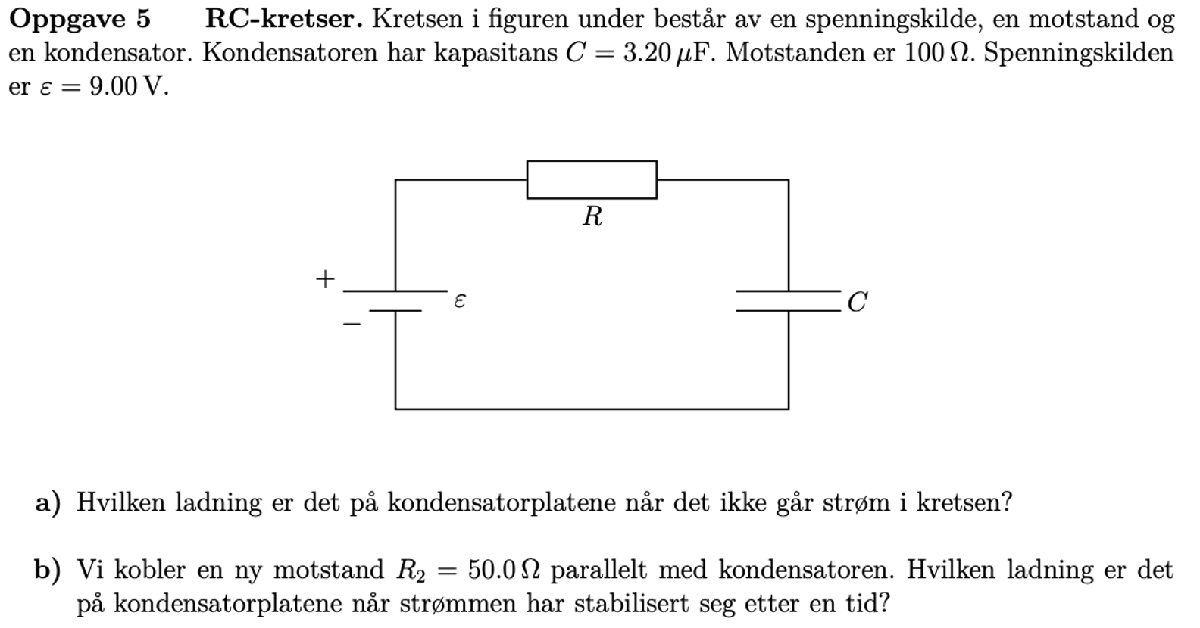

C = 3.20 * 10^-6;
R = 100;
eb = 9;

a)

det går ikke strøm i kretsen når kondensatoren er maks ladet opp, da er epnningen over den lik batteriet og ladningen blir:

Q = C * eb;
signif(Q, 3)

ans =      2.88e-05


b)

Nå vil spenningen over kondensatoren ha endret seg:

I = ohms_lov(eb, R_ser([R 50]), 0)

I =          0.06


V_kondensator = ohms_lov(0, 50, I)

V_kondensator =      3


Q = C * V_kondensator;
signif(Q, 3)

ans =       9.6e-06


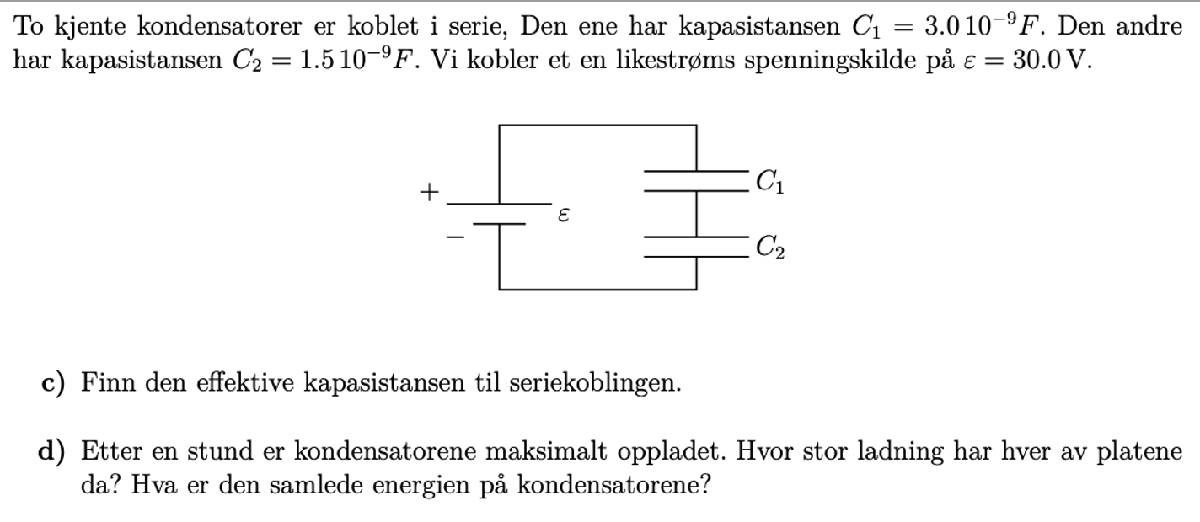

C1 = 3.01 * 10^-9;
C2 = 1.51 * 10^-9;
eb = 30;

c)

C_eff = C_ser([C1 C2])

C_eff =    1.0056e-09


ans =       0.83333


d)

Over begge kondensatorene er den samlede ladningen:

Q_12 = C_eff * eb

Q_12 =    3.0167e-08


Da får vi den samlede energien:

W = Q_12^2/(2*C_eff);
signif(W, 3)

ans =      4.52e-07


*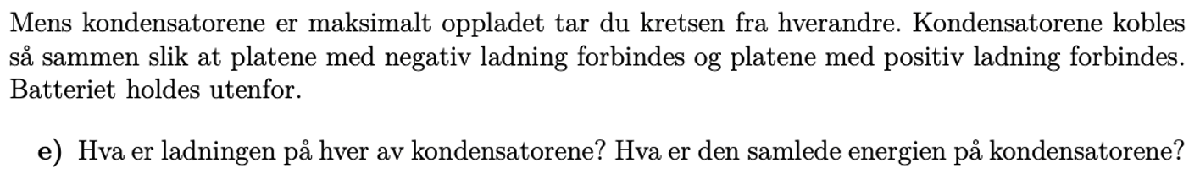

Nå er kondensatorene seriekoblet og total kapasitans:

C_eff = C_par([C1 C2])

C_eff =      4.52e-09


Total ladning på kondesatorene blir da:

Q_12 = 2 * Q_12

Q_12 =    6.0333e-08


Dette gir en ny spenning på

V = Q_12/C_eff

V =        13.348


Som vil være lik over begge kondensaotrene og vi får ladning på hver kondensator:

Q_1 = V*C1

Q_1 =    4.0178e-08


Q_2 = V*C2

Q_2 =    2.0156e-08


Da har vi nå to måter å finne den samelde energien på:


$$W=\frac{{\left(Q_{12} \right)}^2 }{2C_{\mathrm{eff}} }$$


W = Q_12^2/(2*C_eff);
signif(W, 3)

ans =      4.03e-07


og 


$$W=W_1 +W_2 =\frac{Q_1^2 }{2\mathrm{C1}}+\frac{Q_2^2 }{2\mathrm{C2}}$$


W = Q_1^2/(2*C1)+Q_2^2/(2*C2);
signif(W, 3)

ans =      4.03e-07
